# **MATLAB Assignment 3**

# Continuous and Discrete Wavelet Transforms 

**S.S. Hettiarachchi**

**180237G **

**BME**

## **I. Continuous Wavelet Transform**

close all; 
clc;

N = 3000; % Data length
fs = 250; % Sample frequency
scale = 0.01:0.1:2; % Values of scaling factor
time = (-N:N)/fs; % Time scale

**1.1. Introduction**

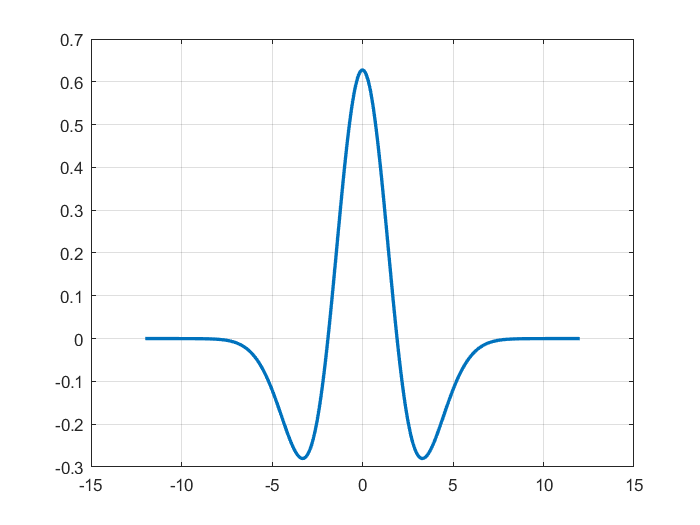

% Normalized Mexican hat function (Scaling factor = 1)
sample_mexican_hat_wavelet = zeros(length(time), length(scale));
scaling_factor =20;
sample_mexican_hat_wavelet(:, scaling_factor) = (2/(sqrt(3*scale(scaling_factor))*pi^(1/4)))*(1-(time/scale(scaling_factor)).^2).*exp(-(time/scale(scaling_factor)).^2 /2);
figure;
plot(time,sample_mexican_hat_wavelet(:,scaling_factor),'LineWidth',2);
grid on;

**1.2.Wavelet properties**

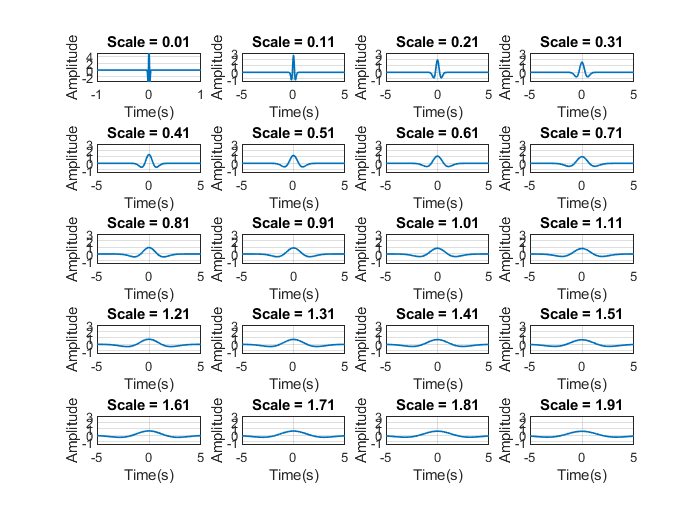

% For daughter wavelets
wavelet = zeros(length(time), length(scale));
wavelet_m = zeros(1,length(scale)); % mean array
wavelet_E = zeros(1,length(scale)); % Energy array

syms x;
syms y;

% plotting Maxican hat wavelet for different scales( 0.01:0.1:2)
figure('Name','Daughter Wavelet');

for i = 1:length(scale)
    wavelet(:, i) = (2/(sqrt(3*scale(i))*pi^(1/4)))*(1-(time/scale(i)).^2).*exp(-(time/scale(i)).^2 /2);
    
    ax = subplot(5,4,i);
    plot(time, wavelet(:, i),'LineWidth',1);
    axis([-5 5 -1.5 3]);
    title(['Scale = ', num2str(scale(i))]);
    xlabel('Time(s)'), ylabel('Amplitude');
    grid on;
    % calculating mean for relavant scale
    wavelet_m(i) = int((2/((sqrt(3*scale(i)))*(pi^(1/4))))*(1-((x/scale(i)).^2)).*exp((-1/2)*(x/scale(i)).^2), 'x', -inf, inf); 
    
    % calculating Energy for relavant scale
    wavelet_E(i) =  int(((2/((sqrt(3*scale(i)))*(pi^(1/4))))*(1-((y/scale(i)).^2)).*exp((-1/2)*(y/scale(i)).^2))^2, 'y', -inf, inf);
end

%subplotting the figures
ax = subplot(5,4,1);
axis([-1 1 -3.5 5]);

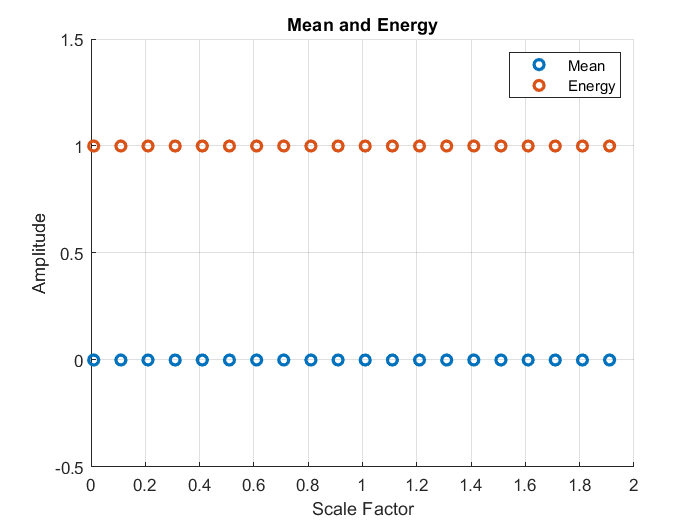

% ploting mean and energy graph
figure('Name','Mean and Energy');
scatter(scale, wavelet_m,'LineWidth',2);
hold on;
scatter(scale, wavelet_E,'LineWidth',2);
hold off;
axis([0 2 -0.5 1.5]);
title('Mean and Energy');
legend('Mean', 'Energy'), xlabel('Scale Factor'), ylabel('Amplitude');
grid on;

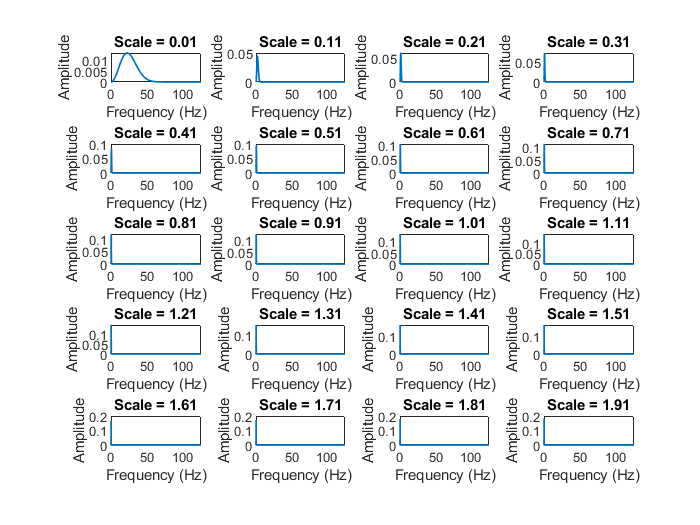

% Generating Spectra of wavelets
figure('Name', 'Spectra of Daughter Wavelets');

for j = 1:length(scale)
    freq_wavelet = fft(wavelet(:, j))/length(wavelet(:, j));
    Hz = linspace(0,fs/2,floor(length(wavelet(:, j))/2)+1);
    
    ax = subplot(5,4,j);
    plot(Hz,2*abs(freq_wavelet(1:length(Hz))),'LineWidth',1)
    title(['Scale = ', num2str(scale(j))]), xlabel('Frequency (Hz)'), ylabel('Amplitude')
end